addpath(genpath('/Users/jiajunhan/Desktop/2022summer/MarkovESValuation-master'));
% T = readtable('DAP_LONGIL_2019_2021.csv');

% load DAP_1h
DAP_LONGIL_2019_2021 = readmatrix('DAP_LONGIL_2019_2021.csv',Delimiter = ',',Range='C:C');
DAP_LONGIL_2019_2021 = reshape(DAP_LONGIL_2019_2021(2:end,:),24,numel(DAP_LONGIL_2019_2021(2:end,:))./24)';

DAP_NORTH_2019_2021 = readmatrix('DAP_NORTH_2019_2021.csv',Delimiter = ',',Range='C:C');
DAP_NORTH_2019_2021 = reshape(DAP_NORTH_2019_2021(2:end,:),24,numel(DAP_NORTH_2019_2021(2:end,:))./24)';

DAP_WEST_2019_2021 = readmatrix('DAP_WEST_2019_2021.csv',Delimiter = ',',Range='C:C');
DAP_WEST_2019_2021 = reshape(DAP_WEST_2019_2021(2:end,:),24,numel(DAP_WEST_2019_2021(2:end,:))./24)';

DAP_NYC_2019_2021 = readmatrix('DAP_NYC_2019_2021.csv',Delimiter = ',',Range='C:C');
DAP_NYC_2019_2021 = reshape(DAP_NYC_2019_2021(2:end,:),24,numel(DAP_NYC_2019_2021(2:end,:))./24)';

% load RTP_5m
RTP_LONGIL_2019_2021 = readmatrix('RTP_LONGIL_2019_2021.csv',Delimiter = ',',Range='C:C');
RTP_LONGIL_2019_2021 = reshape(RTP_LONGIL_2019_2021(2:end,:),288,numel(RTP_LONGIL_2019_2021(2:end,:))./288)';

RTP_NORTH_2019_2021 = readmatrix('RTP_NORTH_2019_2021.csv',Delimiter = ',',Range='C:C');
RTP_NORTH_2019_2021 = reshape(RTP_NORTH_2019_2021(2:end,:),288,numel(RTP_NORTH_2019_2021(2:end,:))./288)';

RTP_WEST_2019_2021 = readmatrix('RTP_WEST_2019_2021.csv',Delimiter = ',',Range='C:C');
RTP_WEST_2019_2021 = reshape(RTP_WEST_2019_2021(2:end,:),288,numel(RTP_WEST_2019_2021(2:end,:))./288)';

RTP_NYC_2019_2021 = readmatrix('RTP_NYC_2019_2021.csv',Delimiter = ',',Range='C:C');
RTP_NYC_2019_2021 = reshape(RTP_NYC_2019_2021(2:end,:),288,numel(RTP_NYC_2019_2021(2:end,:))./288)';


% convert 5min resolution to 1h
RTP_LONGIL_2019_2021_1h=zeros(1096,24)

RTP_LONGIL_2019_2021_1h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

for i=1:1:1096
    RTP_LONGIL_2019_2021_1h(i,:)= mean(reshape(RTP_LONGIL_2019_2021(i,:),12,24),1);
end

% save for Julia
RTP_LONGIL_2019_2021_1h = RTP_LONGIL_2019_2021_1h(1:365,:)'

RTP_LONGIL_2019_2021_1h = 1.0e+03 *

    0.0243    0.0256    0.0323    0.0265    0.0214    0.0172    0.0291    0.0360    0.0267    0.0380    0.0458    0.0450    0.0357    0.0543    0.0648    0.0547    0.2142    0.0511    0.0634    0.0633    0.1017    0.1632    0.1437    0.0366    0.0301    0.0357    0.0336    0.0393    0.0814    0.0443    0.1165    0.1014    0.0653    0.0376    0.0252    0.0259    0.0229    0.1368    0.0225    0.0271    0.0399    0.0322    0.0305    0.0528    0.1537    0.0265    0.0254    0.0303    0.0290    0.0375
    0.0392    0.0253    0.0299    0.0252    0.0241    0.0201    0.0408    0.0713    0.0241    0.0313    0.0360    0.0451    0.0396    0.0608    0.0676    0.0702    0.0764    0.0506    0.0446    0.0652    0.0781    0.1584    0.1718    0.0449    0.0260    0.0370    0.0333    0.0330    0.0747    0.0439    0.1180    0.0710    0.0611    0.0363    0.0286    0.0232    0.0216    0.0560    0.0250    0.0275    0.0570    0.0378    0.0317    0.0411    0.0651    0.0293  

save('RTP_LONGIL_2019_2021_1h.mat','RTP_LONGIL_2019_2021_1h')

DAP_LONGIL_2019_2021_Julia = DAP_LONGIL_2019_2021(1:365,:)'

DAP_LONGIL_2019_2021_Julia =    51.9000   42.3800   52.0700   47.6400   39.9500   37.2300   39.9300   57.2000   42.5100   42.0900   55.5300   86.2300   62.6200   61.3500   74.5100   54.3300   58.9900   59.0700   66.5500  101.4800  136.0100  177.6800  126.2100   69.1200   43.6000   62.7700   59.5800   63.4800   70.9100   64.9700  131.6800  157.6000  140.0000   59.0000   44.0300   45.6800   39.8400   44.5700   36.1200   33.6400   38.2500   48.9100   57.3300   47.1600   41.9700   35.1100   33.4800   35.6400   44.0200   42.1500
   42.5900   38.2400   44.9000   42.3000   35.9700   32.7000   35.9600   45.1700   36.6400   38.5300   49.7200   78.7600   60.4600   59.7300   70.5700   48.8600   55.5600   57.0000   62.6700   94.7100  127.8300  159.7100  116.7200   63.0500   41.3300   56.5600   57.1700   53.4700   61.4600   58.9700  124.7300  144.5400  123.6700   55.1900   41.4400   39.4500   36.8500   36.5700   33.5600   31.7600   35.6400   43.6000   52.4800   44.7400   37.6100   33.6300   31.2700

save('DAP_LONGIL_2019_2021.mat','DAP_LONGIL_2019_2021_Julia')

% convert 5min resolution to 1h
RTP_NORTH_2019_2021_1h=zeros(1096,24)

RTP_NORTH_2019_2021_1h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for i=1:1:1096
    RTP_NORTH_2019_2021_1h(i,:)= mean(reshape(RTP_NORTH_2019_2021(i,:),12,24),1);
end

% save for Julia
RTP_NORTH_2019_2021_1h = RTP_NORTH_2019_2021_1h(1:365,:)'

RTP_NORTH_2019_2021_1h = 1.0e+03 *

    0.0063    0.0217    0.0279    0.0221    0.0181    0.0148    0.0151    0.0289    0.0230    0.0290    0.0074    0.0371    0.0308    0.0378    0.0515    0.0332    0.0420    0.0456    0.0370    0.0627    0.0090    0.0429    0.1156    0.0202    0.0231    0.0276    0.0290    0.0310    0.0477    0.0311    0.0190    0.0315    0.0553    0.0311    0.0215    0.0100    0.0193    0.1192    0.0189    0.0223    0.0333    0.0276    0.0266    0.0449    0.1154    0.0228    0.0175    0.0261    0.0249    0.0183
    0.0063    0.0215    0.0258    0.0208    0.0204    0.0166    0.0165    0.0595    0.0208    0.0258    0.0259    0.0373    0.0343    0.0351    0.0407    0.0258    0.0399    0.0454    0.0348    0.0600    0.0095    0.0129    0.0453    0.0198    0.0194    0.0293    0.0286    0.0256    0.0479    0.0317    0.0188    0.0580    0.0518    0.0303    0.0219    0.0109    0.0178    0.0427    0.0185    0.0227    0.0479    0.0321    0.0276    0.0310    0.0467    0.0226   

save('RTP_NORTH_2019_2021_1h.mat','RTP_NORTH_2019_2021_1h')

DAP_NORTH_2019_2021_Julia = DAP_NORTH_2019_2021(1:365,:)'

DAP_NORTH_2019_2021_Julia =    19.6300   24.2300   34.7300   27.7300   25.4000   21.1200   24.6500   25.7800   23.6600   13.1900   17.0000   30.8900   30.6800   36.4700   42.3300   32.9100   29.2600   47.4200   32.7900   63.1000   79.5600  110.5200  103.5400   30.7500   29.7100   38.5100   34.0000   26.2100   48.2300   39.0800   52.3900   92.1600   64.7200   26.8600   24.6000   28.7400   25.6400   27.6500   17.3100   20.3700   26.7200   32.4600   34.5400   25.5800   15.5600   26.7700   20.5100   27.4900   29.1500   29.1500
   18.8100   22.8200   29.7200   25.5400   21.2100   17.8600   21.5000   18.2400   22.7000   11.8300   14.5800   26.6100   28.9200   31.0900   35.8200   27.9000   28.2000   42.3400   29.1900   54.8900   77.3400  100.6400   89.6900   27.6300   27.9100   32.0600   30.2700   26.7600   40.9000   29.2900   43.4500   79.1300   58.8200   27.6000   21.4800   24.4000   27.4200   24.8400   16.9000   18.0700   20.4300   29.2100   30.2500   20.8300   17.4400   24.4800   21.2000 

save('DAP_NORTH_2019_2021.mat','DAP_NORTH_2019_2021_Julia')

% convert 5min resolution to 1h
RTP_WEST_2019_2021_1h=zeros(1096,24)

RTP_WEST_2019_2021_1h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

for i=1:1:1096
    RTP_WEST_2019_2021_1h(i,:)= mean(reshape(RTP_WEST_2019_2021(i,:),12,24),1);
end

% save for Julia
RTP_WEST_2019_2021_1h = RTP_WEST_2019_2021_1h(1:365,:)'

RTP_WEST_2019_2021_1h =     8.9850   76.2867   31.2367   30.8000   18.2200   19.1817   17.4433   28.4267   23.9067   29.9867   22.0017  110.6958   39.9058   34.7625   65.8333   31.1958   49.4325   40.7675   34.7617   45.8817   19.5965   65.0475  100.4189   22.0375   51.1458   50.8367   28.9033   32.4925   44.9775   28.8417   18.3425   29.9275   54.4450   32.1200   21.1783   11.0925   20.2575  122.7300   18.6475   23.3117   34.0625   28.9833   25.5483   45.1467  118.9950   22.5242   18.7900   27.7350   25.3200   20.8883
    8.6375   58.4025   25.7775   24.6767   20.5867   16.3183   18.5217   59.4125   20.5358   26.3058   26.5075   99.3558   63.4650   33.3742   51.8400   25.5708   38.5350   40.3258   32.6833   50.4608   15.9633   30.6900   48.2342   22.6933   47.0975   40.1267   28.3300   26.6192   44.7217   29.5008   18.2433   53.5637   51.2633   30.8992   21.4242   11.5867   18.6383   43.4308   18.7375   23.8558   54.6575   33.5742   26.6733   32.0275   48.2437   22.6117   18.0842   25

save('RTP_WEST_2019_2021_1h.mat','RTP_WEST_2019_2021_1h')

DAP_WEST_2019_2021_Julia = DAP_WEST_2019_2021(1:365,:)'

DAP_WEST_2019_2021_Julia =    22.5800   26.1800   36.3200   31.5500   28.4500   22.5300   27.7100   28.2600   45.0000   40.3500   77.1100   77.3700   31.9000   35.0700   41.0000   34.0400   33.5100   45.0600   35.4600   58.6200   82.0000  135.0000   95.1600   36.1200   45.9300   67.4100   41.0000   29.1100   46.2200   42.0500  115.0000  100.0900   67.2300   28.9100   25.6200   30.6300   33.4400   29.4100   19.6800   22.5900   29.4300   33.8800   35.4300   28.6500   24.9000   27.9100   23.1300   28.4100   29.8500   31.0200
   20.9200   24.6000   31.4500   28.6300   23.9100   18.9400   24.2300   21.5200   36.9100   31.0000   51.0700   48.1500   30.3200   31.1600   34.8200   29.6700   31.4700   40.7800   32.2300   51.2000   77.5300  117.2500   83.7100   32.1500   35.4000   46.5000   36.0000   28.2100   39.5300   33.1800   57.3600   88.0900   60.9300   29.2400   22.5700   26.0900   30.5500   26.1900   18.9300   20.4400   23.3500   30.5800   31.5800   24.1900   22.2600   25.9900   23.1400  

save('DAP_WEST_2019_2021.mat','DAP_WEST_2019_2021_Julia')

% convert 5min resolution to 1h
RTP_NYC_2019_2021_1h=zeros(1096,24)

RTP_NYC_2019_2021_1h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

for i=1:1:1096
    RTP_NYC_2019_2021_1h(i,:)= mean(reshape(RTP_NYC_2019_2021(i,:),12,24),1);
end

% save for Julia
RTP_NYC_2019_2021_1h = RTP_NYC_2019_2021_1h(1:365,:)'

RTP_NYC_2019_2021_1h =    24.0450   24.8592   30.6458   25.7600   20.6942   16.8150   28.5258   34.3492   25.9067   39.8158   47.3783   43.9600   34.5208   41.4292   57.1892   40.9692   48.5725   49.3000   42.7942   61.3358   81.7157  140.6433  125.7736   35.9108   29.3600   40.8167   32.5317   41.4092   52.9000   34.7833  116.3308  100.8508   63.9558   36.4767   24.4442   20.8617   22.2550  131.1083   21.9408   26.5233   38.2083   31.2533   29.6383   51.7208  134.6542   25.7308   24.7817   29.6125   28.0708   36.8650
   22.2992   24.5383   27.9033   24.5692   23.3875   19.5458   28.3517   68.5683   23.4833   30.6883   36.4075   43.9358   38.4217   38.6983   45.3792   40.2500   45.2225   48.9775   41.3875   63.1908   56.5342  131.8967  104.5467   42.4658   25.4042   43.7650   32.6367   41.6267   53.2458   35.3367  118.0550   70.0642   59.8333   35.2908   25.0875   19.4708   20.4608   47.2792   24.4867   26.8758   55.2425   36.4433   30.7767   40.0808   57.2513   26.0600   21.3517   27.

save('RTP_NYC_2019_2021_1h.mat','RTP_NYC_2019_2021_1h')

DAP_NYC_2019_2021_Julia = DAP_NYC_2019_2021(1:365,:)'

DAP_NYC_2019_2021_Julia =    34.6900   33.6000   42.4500   41.8400   32.9300   28.7600   33.9500   40.6300   33.8900   34.2800   47.7200   65.3600   45.7400   41.1100   47.9700   43.5100   48.8200   51.1400   51.2100   77.9500  121.8000  142.1900  115.1900   60.9500   41.3000   56.2100   50.1400   44.1300   58.6900   53.7500  123.6500  150.0300  128.5900   39.9900   31.2600   34.5500   36.0800   32.5000   28.4200   28.0600   33.9000   37.6700   39.9700   40.4900   35.6400   31.0700   28.9700   33.7800   33.4300   39.3300
   29.3500   32.4100   36.6900   36.9000   29.2800   24.5100   30.2200   37.0700   28.7700   31.2400   43.8700   61.1400   43.6800   38.4300   41.1700   40.4400   43.6000   46.7200   47.9900   69.5200  112.6900  125.9300  111.6300   53.8200   37.9600   47.5700   46.3800   36.0100   46.7600   46.5900  114.9400  140.4000  106.0800   37.7000   28.5700   29.6000   32.9100   29.2200   25.9100   26.2300   31.4600   33.9600   35.7200   36.6300   31.5300   28.6200   25.7100   

save('DAP_NYC_2019_2021.mat','DAP_NYC_2019_2021_Julia')

% % DAM should be the 1st day for virtual bidding in Julia
% RTP_LONGIL_2019_2021_1h_vb = RTP_LONGIL_2019_2021_1h(2:366,:)'
% save('RTP_LONGIL_2019_2021_1h_vb.mat','RTP_LONGIL_2019_2021_1h_vb')
% 
% DAP_LONGIL_2019_2021_Julia_vb = DAP_LONGIL_2019_2021(1:365,:)'
% save('DAP_LONGIL_2019_2021_vb.mat','DAP_LONGIL_2019_2021_Julia_vb')


% (and fianlly convert it to 1h frequency)
RTP_5m = cat(1,RTP_LONGIL_2019_2021,RTP_NORTH_2019_2021,RTP_WEST_2019_2021,RTP_NYC_2019_2021);

RTP_1h=zeros(1,24);
for i=1:1:1096*4
    RTP_1h(i,:)= mean(reshape(RTP_5m(i,:),12,24),1);
end

% 
% RTP_1h_t=zeros(2,24);
% for i=1:1:1096*4
%     RTP_1h_t(i,:)= mean(reshape(RTP_5m(i,:),12,24),1);
% end
% 
% a = isequal(RTP_1h_t, RTP_1h)

%  DAP_1d_mean
DAP_LONGIL_dm = mean(DAP_LONGIL_2019_2021,2);
DAP_NORTH_dm = mean(DAP_NORTH_2019_2021,2);
DAP_WEST_dm = mean(DAP_WEST_2019_2021,2);
DAP_NYC_dm = mean(DAP_NYC_2019_2021,2);

% RTP_1d_mean
RTP_LONGIL_dm = mean(RTP_LONGIL_2019_2021,2);
RTP_NORTH_dm = mean(RTP_NORTH_2019_2021,2);
RTP_WEST_dm = mean(RTP_WEST_2019_2021,2);
RTP_NYC_dm = mean(RTP_NYC_2019_2021,2);

% DAP_1d - RTP_1d
diff_LONGIL_1d = DAP_LONGIL_dm - RTP_LONGIL_dm;
diff_NORTH_1d = DAP_NORTH_dm - RTP_NORTH_dm;
diff_WEST_1d = DAP_WEST_dm - RTP_WEST_dm;
diff_NYC_1d = DAP_NYC_dm - RTP_NYC_dm;


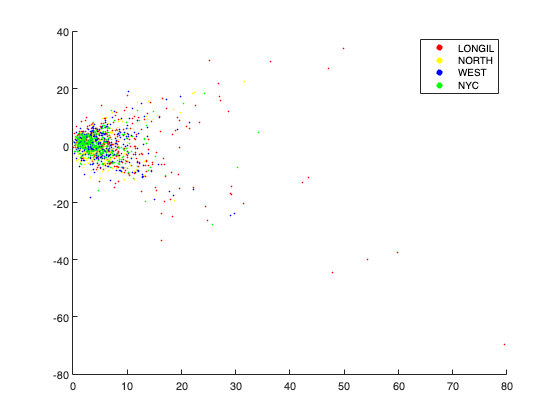


% DAP-RTP of the same day every year
d_LONGIL_sd = reshape(diff_LONGIL_1d(1:end-1,:),365,3);
d_NORTH_sd = reshape(diff_NORTH_1d(1:end-1,:),365,3);
d_WEST_sd = reshape(diff_WEST_1d(1:end-1,:),365,3);
d_NYC_sd = reshape(diff_NYC_1d(1:end-1,:),365,3);

d_LONGIL_sd_avg = mean(d_LONGIL_sd,2);
d_LONGIL_sd_std = std(d_LONGIL_sd,1,2);
d_NORTH_sd_avg = mean(d_NORTH_sd,2);
d_NORTH_sd_std = std(d_NORTH_sd,1,2);

d_WEST_sd_avg = mean(d_WEST_sd,2);
d_WEST_sd_std = std(d_WEST_sd,1,2);

d_NYC_sd_avg = mean(d_NYC_sd,2);
d_NYC_sd_std = std(d_NYC_sd,1,2);

scatter(d_LONGIL_sd_std,d_LONGIL_sd_avg,3,'filled','red')
hold on
scatter(d_NORTH_sd_std,d_NORTH_sd_avg,3,'filled','yellow')
hold on
scatter(d_WEST_sd_std,d_WEST_sd_avg,3,'filled','blue')
hold on
scatter(d_NYC_sd_std,d_NYC_sd_avg,3,'filled','green')
hold off
legend("show",'LONGIL','NORTH','WEST','NYC')

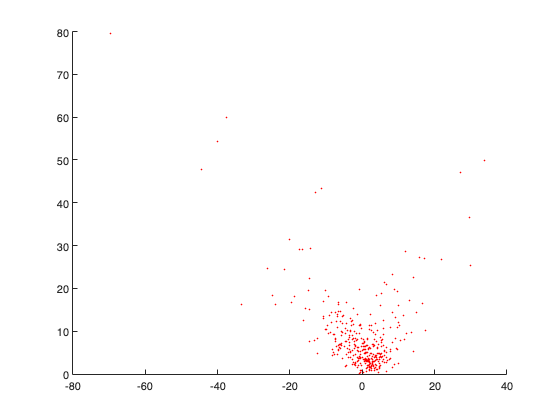

scatter(d_LONGIL_sd_avg,d_LONGIL_sd_std,3,'filled','red')

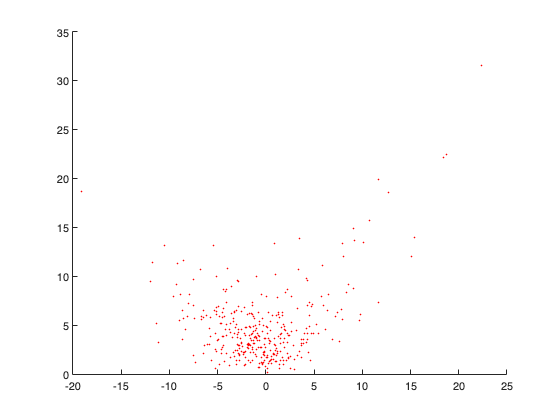

scatter(d_NORTH_sd_avg,d_NORTH_sd_std,3,'filled','red')

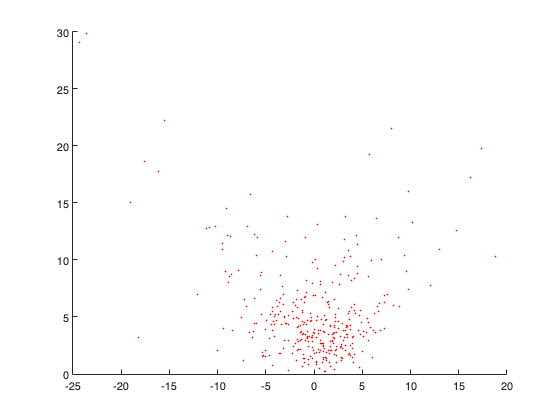

scatter(d_WEST_sd_avg,d_WEST_sd_std,3,'filled','red')

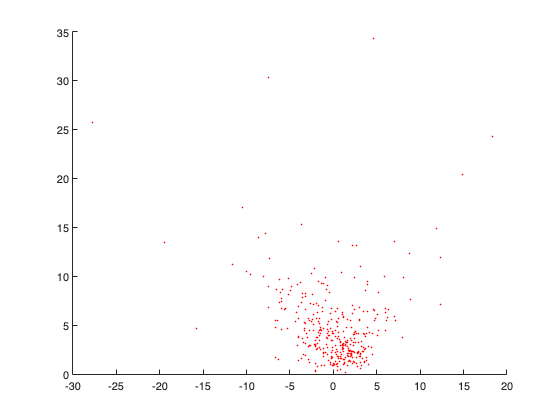

scatter(d_NYC_sd_avg,d_NYC_sd_std,3,'filled','red')

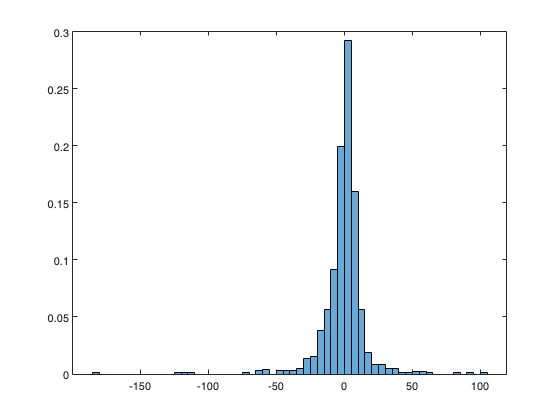

histogram(diff_LONGIL_1d,'Normalization','probability',BinWidth=5);
hold off

% DAP-RTP of 1-hour resolution
d_LONGIL = DAP_LONGIL_2019_2021 - RTP_1h(1:1096,:);
d_NORTH = DAP_NORTH_2019_2021 - RTP_1h(1097:1096*2,:);
d_WEST = DAP_WEST_2019_2021 - RTP_1h(1096*2+1:1096*3,:);
d_NYC = DAP_NYC_2019_2021 - RTP_1h(1096*3+1:1096*4,:);


d_LONGIL_1h_avg = mean(d_LONGIL',2)

d_LONGIL_1h_avg =     0.3427
   -1.4118
   -0.3386
    1.2371
   -0.2158
   -0.6006
   -0.2176
    0.2249
   -0.1516
   -0.0393


d_LONGIL_1h_std = std(d_LONGIL,1,1)

d_LONGIL_1h_std =    46.3483   40.6700   35.3968   23.7686   18.1895   12.9761   11.5492   11.5906   12.4538   12.5951   16.0528   20.0938   46.0618   26.0880   22.1324   24.5891   21.9748   40.6421   40.6739   46.1861   58.4581   98.4119   47.2380   43.1743



d_NORTH_1h_avg = mean(d_NORTH',2)

d_NORTH_1h_avg =    -0.8141
   -0.3086
    0.0752
   -0.0004
    0.0693
   -0.5583
    0.1841
   -0.3170
   -0.5219
   -0.3853


d_NORTH_1h_std = std(d_NORTH,1,1)

d_NORTH_1h_std =    28.2840   24.3632   21.3407   15.8315   18.5356   11.7277   24.5631   11.3896    7.7289    9.5445   12.2392   17.5724   16.5008   27.0502   19.5655   18.0430   43.0099   20.2077   15.3643   17.9871   20.6872   19.1461   31.3212   22.3003



d_WEST_1h_avg = mean(d_WEST',2)

d_WEST_1h_avg =     0.4728
    0.2008
   -0.5877
   -0.4972
   -0.5245
   -0.0985
    0.5483
    0.1250
    0.0014
    0.1530


d_WEST_1h_std = std(d_WEST,1,1)

d_WEST_1h_std =    22.6182   19.5830   14.5007    9.5623   10.2704    9.7331   20.9097    7.3036    6.5425    8.1596   12.6591   16.8153   19.4577   21.9682   19.2054   21.4659   23.7463   21.9965   24.8551   27.3193   26.7118   25.0597   28.3159   20.0717



d_NYC_1h_avg = mean(d_NYC',2)

d_NYC_1h_avg =    -0.2653
    0.0257
   -0.0356
   -0.1518
   -0.6223
   -0.6989
   -0.1097
   -0.0119
   -0.1615
   -0.1574


d_NYC_1h_std = std(d_NYC,1,1)

d_NYC_1h_std =    20.3306   15.0362   12.3117   10.0156   11.5775    9.9738    7.9155    8.0599    8.1874    7.6594    8.3829   13.1609   15.0203   15.9708   15.7683   18.4622   15.4459   15.6111   17.4405   18.9637   17.4462   26.5425   32.7422   20.2093


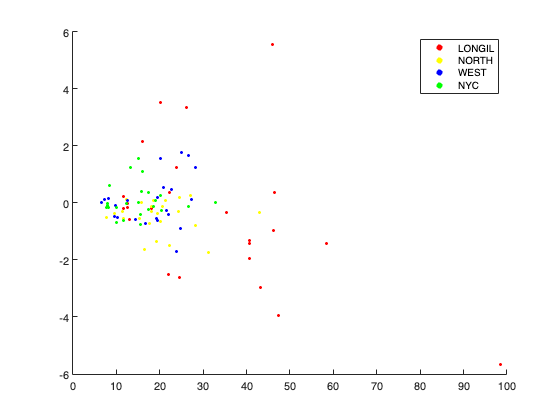


scatter(d_LONGIL_1h_std,d_LONGIL_1h_avg,10,'filled','red')
hold on
scatter(d_NORTH_1h_std,d_NORTH_1h_avg,10,'filled','yellow')
hold on
scatter(d_WEST_1h_std,d_WEST_1h_avg,10,'filled','blue')
hold on
scatter(d_NYC_1h_std,d_NYC_1h_avg,10,'filled','green')
hold off
legend("show",'LONGIL','NORTH','WEST','NYC')

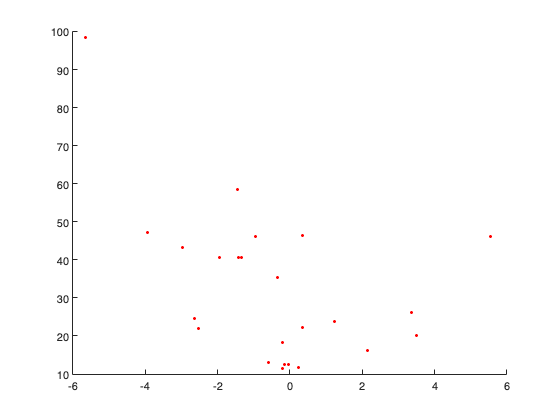

scatter(d_LONGIL_1h_avg,d_LONGIL_1h_std,10,'filled','red')

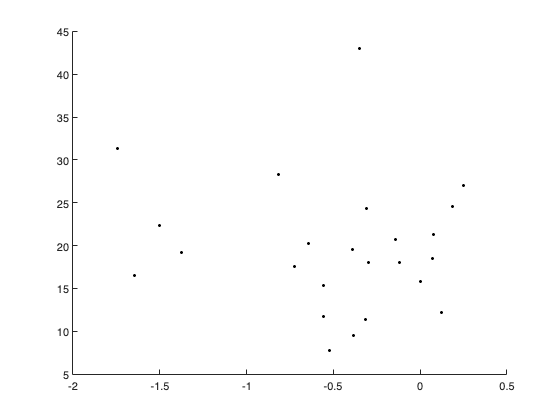

scatter(d_NORTH_1h_avg,d_NORTH_1h_std,10,'filled','black')

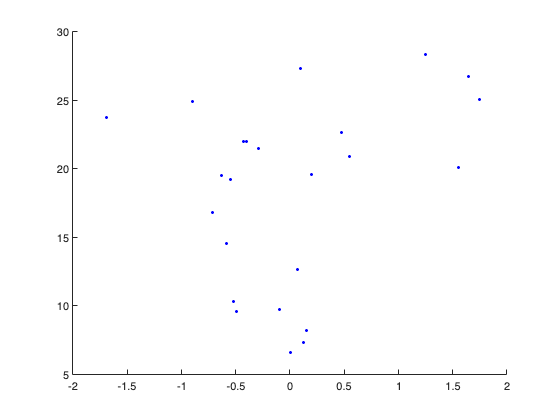

scatter(d_WEST_1h_avg,d_WEST_1h_std,10,'filled','blue')

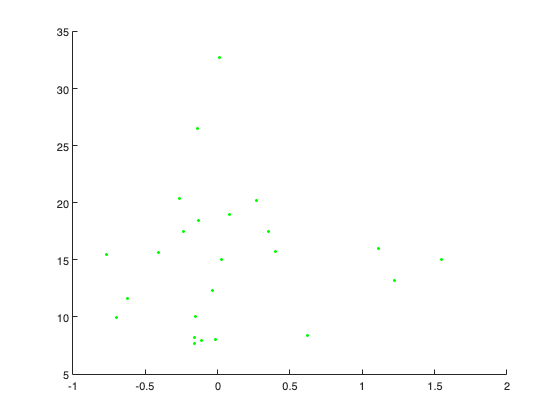

scatter(d_NYC_1h_avg,d_NYC_1h_std,10,'filled','green')

% daily average of difference
d_LONGIL_dm = mean(d_LONGIL,2);
d_NORTH_dm = mean(d_NORTH,2);
d_WEST_dm = mean(d_WEST,2);
d_NYC_dm = mean(d_NYC,2);

% dev_LONGIL_dm = zeros(1096,1)
% for i=1:1:1096
%     dev_LONGIL_dm(i,:) = d_LONGIL_dm(i,:) - mean(d_LONGIL_dm,1)

d_total = cat(1,d_LONGIL_dm,d_NORTH_dm,d_WEST_dm,d_NYC_dm)

d_total =    10.1341
   11.5092
    9.6506
    8.7186
    5.5794
   -1.1630
    6.4714
    6.0624
    1.4065
    0.0433


% find(d_total<0)

% std_1h
std_LONGIL = std(d_LONGIL,1,2);
std_NORTH = std(d_NORTH,1,2);
std_WEST = std(d_WEST,1,2);
std_NYC = std(d_NYC,1,2);

% normplot(d_LONGIL_dm);
% normplot(d_NORTH_dm);
% normplot(d_WEST_dm);
% normplot(d_NYC_dm);
% [H,P,LSTAT,CV] = lillietest(d_LONGIL_dm,0.05)

% histogram graph of daily average of difference in 4 zones
histogram(d_LONGIL_dm,'Normalization','probability',BinWidth=5)
hold off

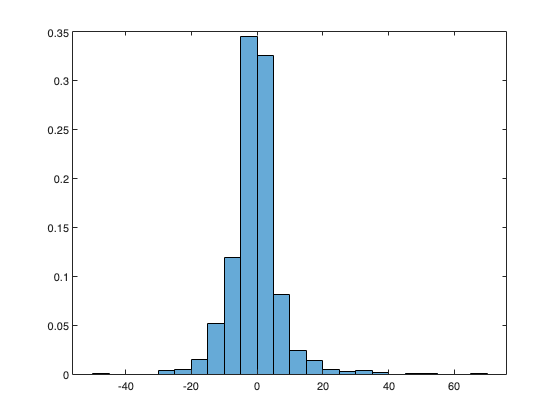

histogram(d_NORTH_dm,'Normalization','probability',BinWidth=5)
hold off

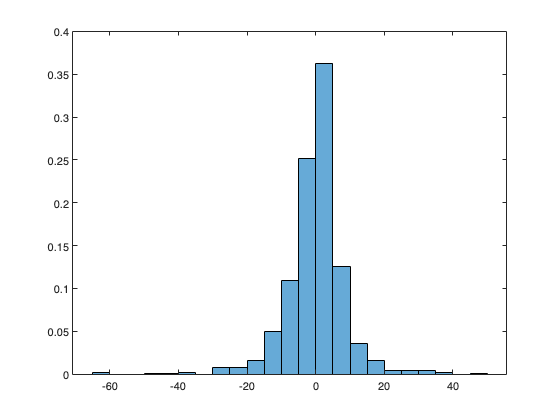

histogram(d_WEST_dm,'Normalization','probability',BinWidth=5)
hold off

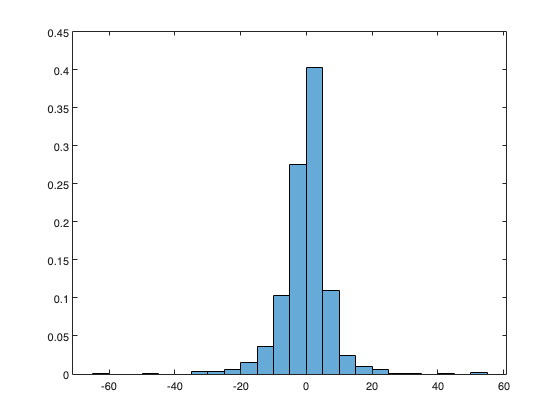

histogram(d_NYC_dm,'Normalization','probability',BinWidth=5)

histogram(d_LONGIL_dm,'Normalization','probability',BinWidth=5)
hold off

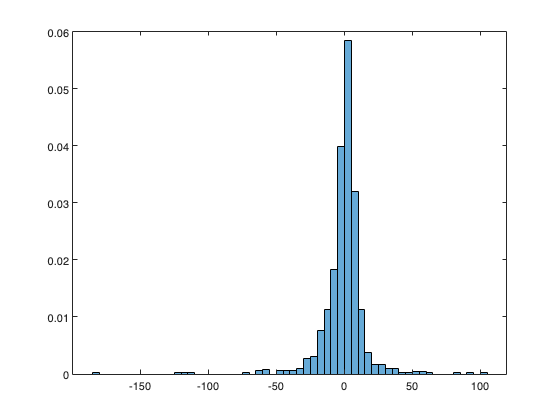

histogram(d_LONGIL_dm,'Normalization','pdf',BinWidth=5)
hold off

% mean(reshape(RTP_LONGIL_2019_2021(1,:),12,24),1)